# Limitaciones computacionales

Las variables que se almacenan en una computadora pueden asumir un amplio rango de valores.

MATLAB incluye funciones para identificar los números reales más grandes y los enteros más grandes que el programa puede procesar.

**Nota:** Existe un límite acerca de cuán pequeño o cuán grande puede ser un número manejado por los programas de cómputo.

A continuación se detallan estas funciones.

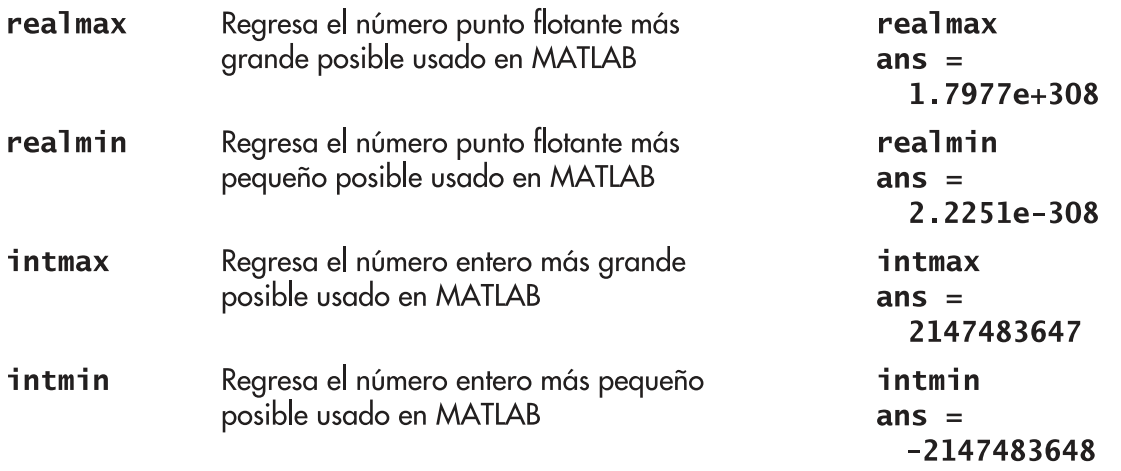

## Desbordamiento de exponente

Es un error resultado de un cálculo que es demasiado grande para que el programa de cómputo lo pueda manejar.

El `realmax` corresponde a aproximadamente $2^{1024}$ dado que las computadoras realizan sus cálculos en aritmética binaria.

clear

x = 2.5e200;
y = 1e200;

z = x*y         % Dado que el resultado supera el valor realmax se genera un desbordamiento.

z = Inf

## Subdesbordamiento de exponente

Es un error similar al desbordamiento de exponente. Es un error resultado de un cálculo que es demasiado pequeño como para que la computadora lo distinga de cero.

clear

x = 2.5e-200;
y = 1e200;

z = x/y

z = 0

Hay que considerar un reordenamiento cuando los cálculos se hacen entre números muy grandes.

2.5e200*2e200*1e-100

ans = Inf


% Genera un error porque MATLAB realiza los cálculos de derecha a
% izquierda, entonces la operación 2.5e200*2e200 es igual a 5e400,
% superando el límite permitido. Sin embargo, reordenando las operaciones
% se lo puede evitar.

2.5e200*1e-100*2e200

ans = 5.0000e+300


% Este último resultado si está dentro del límite y no genera un
% desbordamiento.

**Recomendación:** La planeación cuidadosa puede ayudar a evitar el desbordamiento o subdesbordamiento en los cálculos.